# 计算动态性能指标

clear
MatName = "Chip1_102400_LowSpeed.mat"

MatName = "Chip1_102400_LowSpeed.mat"

load(MatName)
% data_N4_calib: 4 digital code for Gain-calculation
% data_N4: 4 digital code for sample

## Gain Calculation

gain = deltaGain(data_N4_calib(:,2:end), 10);

引用了已清除的变量 data_N4_calib。


GAIN = mean(gain)

figure
plot(gain);
hold on;
plot(ones([1, length(gain)])*GAIN);
hold off;

legend(["LSB calibration","LSB average"])
xlabel("Sample Point");
ylabel("Gain with Calibration")
xlim([0, length(gain)])

## Sample Points Postprocessing

GAIN = mean([GAIN_PLUS, GAIN_MIN]);
Vref = 1.8;
N_SUB = 5;
LSB_SUB = Vref / 2^N_SUB;
fs = 2E6;                       % sample rate = 2MHz;
% N_Sample = length(data_N4);     % sample points = 102400;
N_Sample = length(Vout_N4);
J = 3;
M = 1280;
Num_2pi = N_Sample / M;         %
fin = J/M*fs;                   % input frequency = 3/1280*fs;
% Vout_N4 = data_N4 * LSB_SUB;    % change ditigal code to analog voltage;

### flash performance

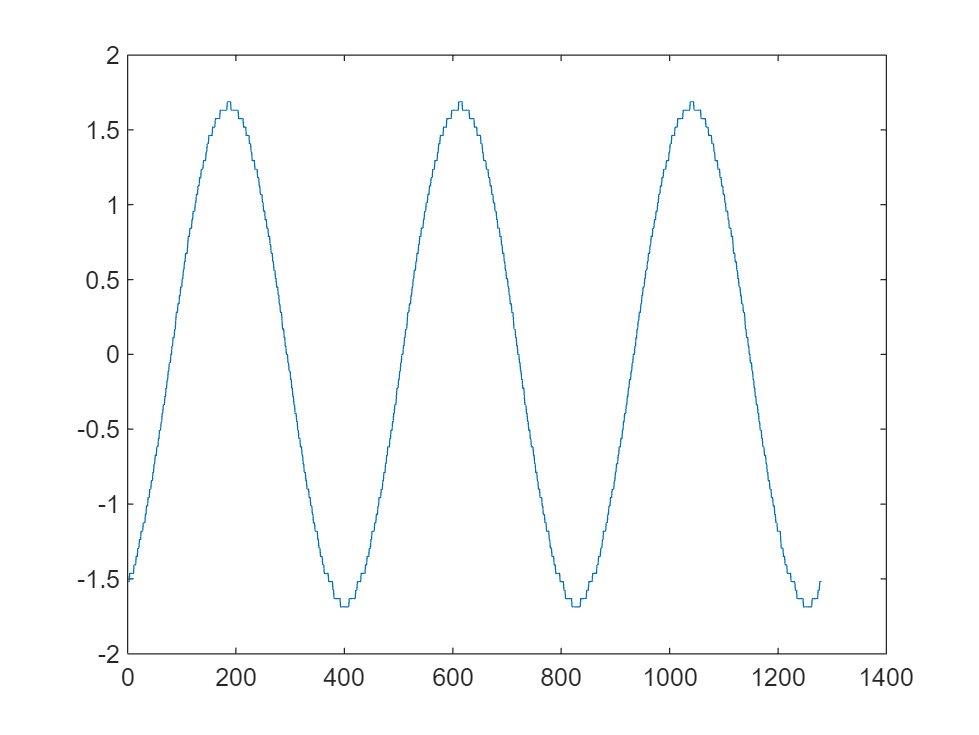

figure
plot(Vout_N4(1:M,1));

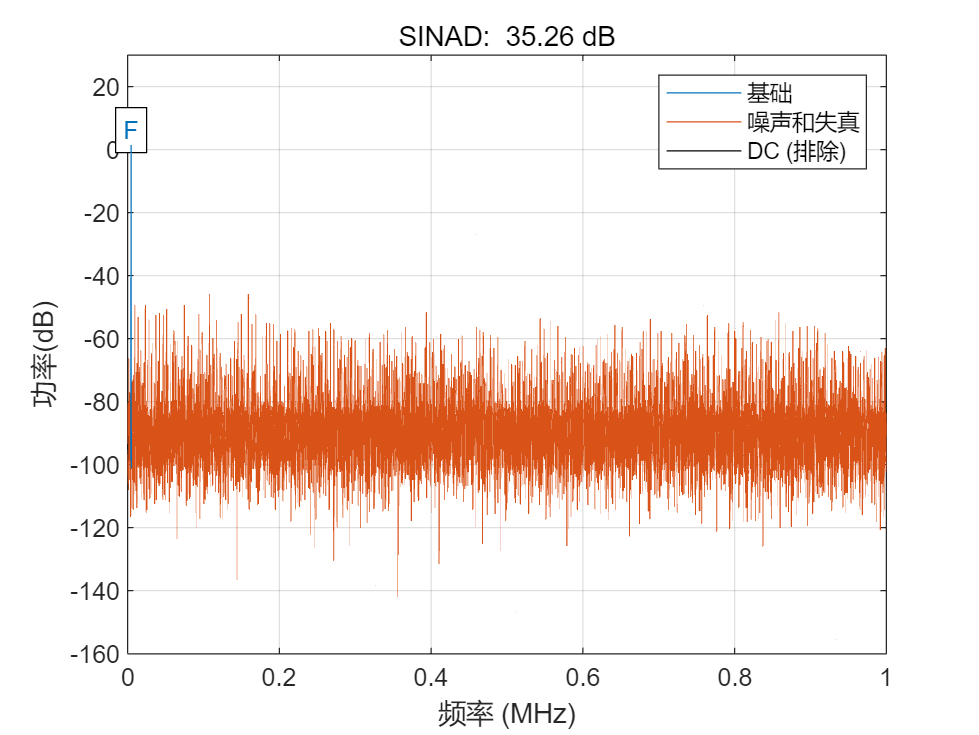

ans = 35.2641

sinad(Vout_N4(:,1), fs)

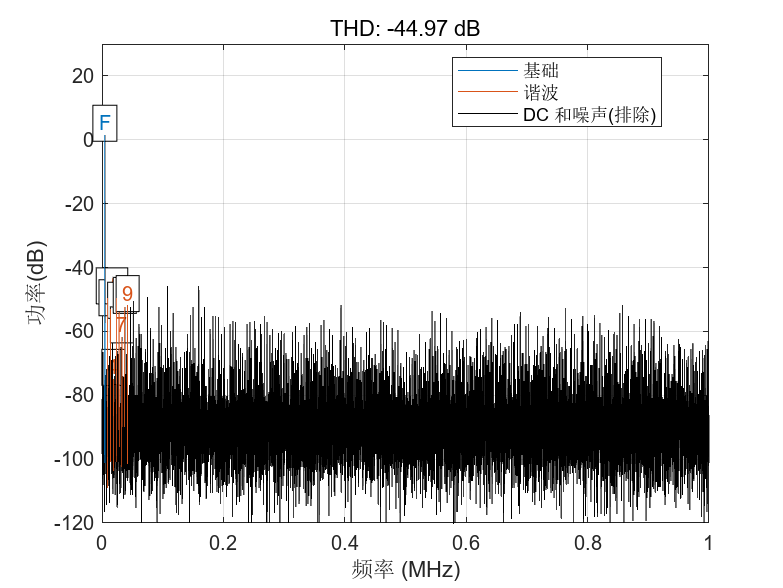

ans = -44.9691

thd(Vout_N4(:,1), fs, 9, "aliased")

### System Performance

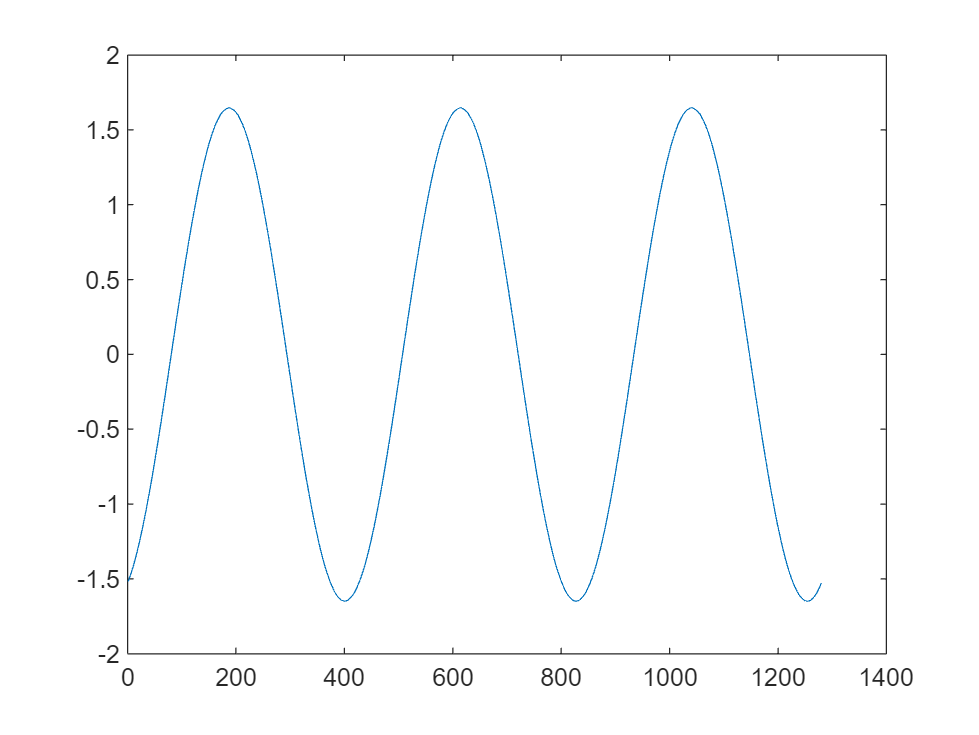

Vout_without_calib = Calib_Gain(Vout_N4, 16);
figure
plot(Vout_without_calib(1:M));

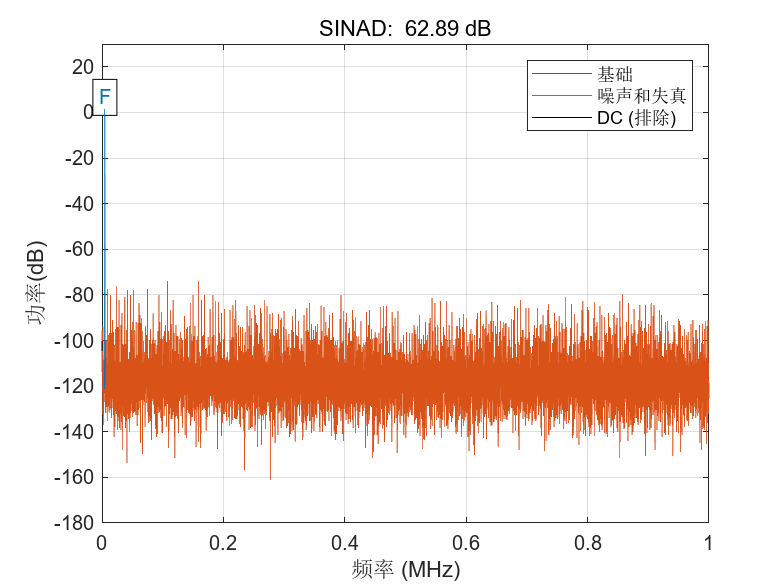

ans = 62.8873

sinad(Vout_without_calib, fs)

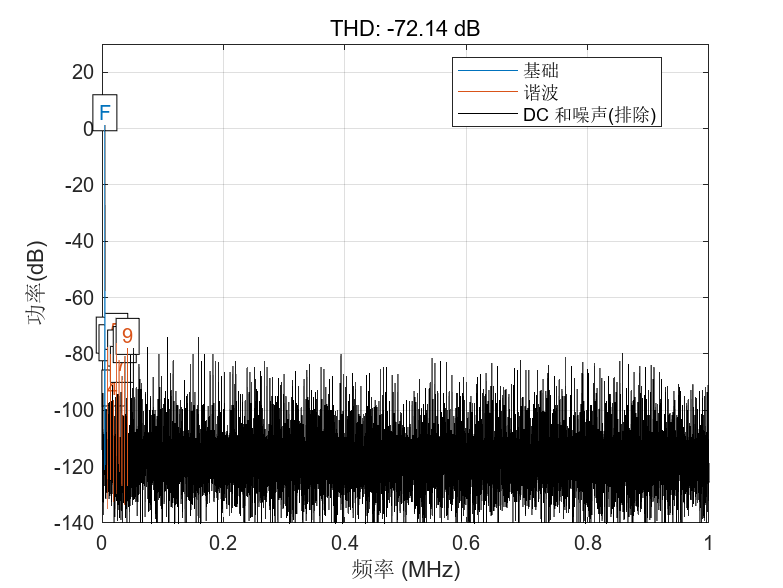

ans = -72.1445

thd(Vout_without_calib, fs, 9, "aliased")

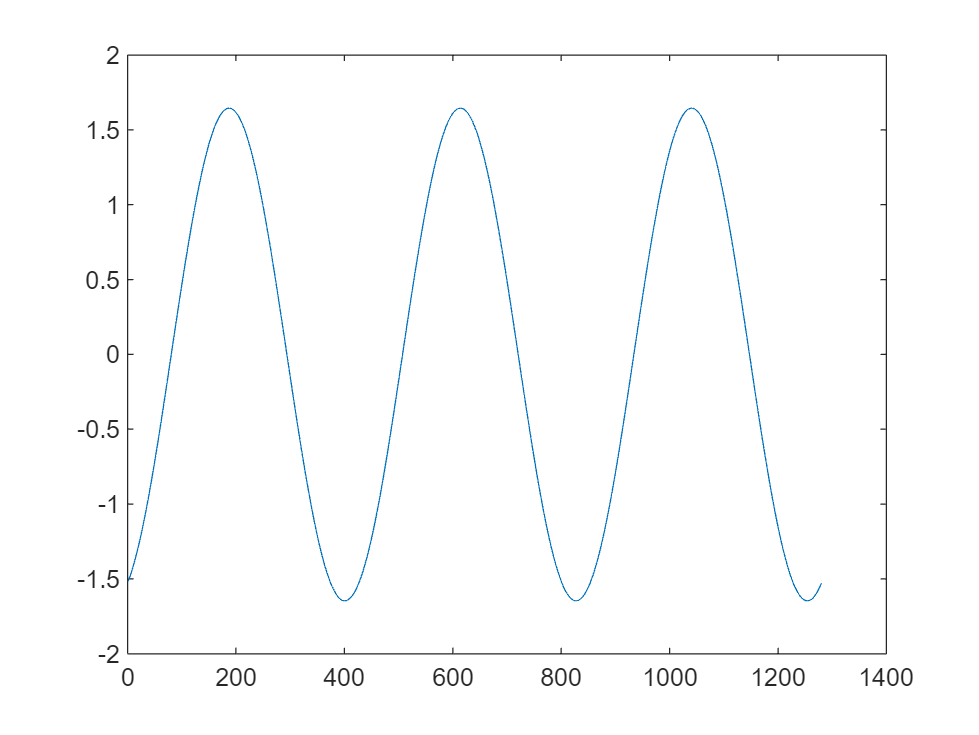


Vout_mean_calib = Calib_Gain(Vout_N4, GAIN);
figure
plot(Vout_mean_calib(1:M));

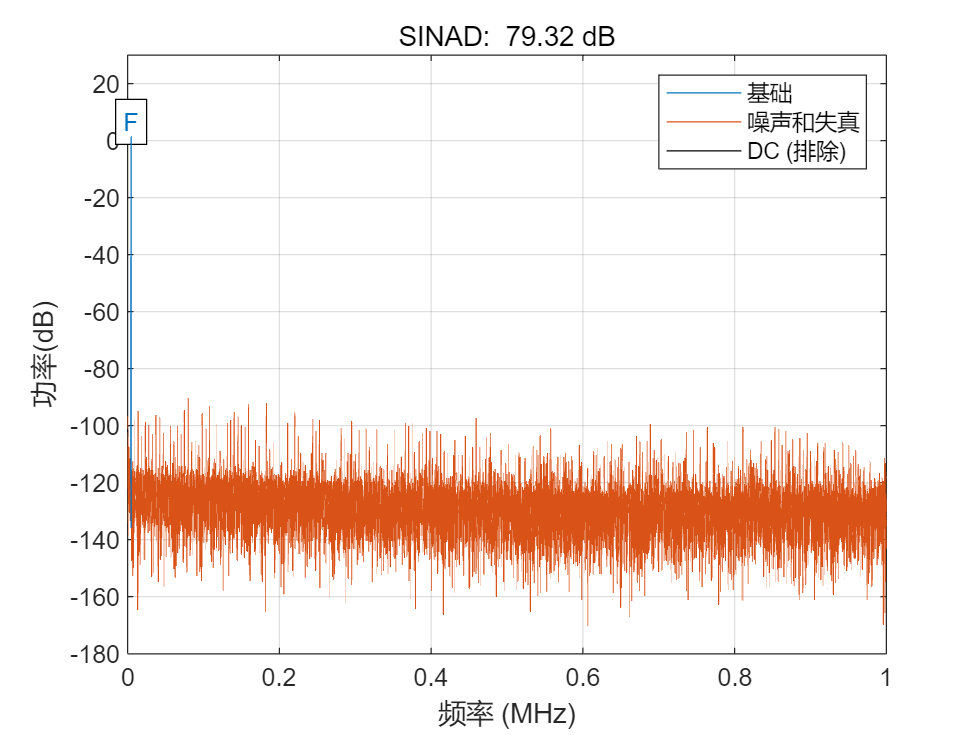

ans = 79.3250

sinad(Vout_mean_calib, fs)

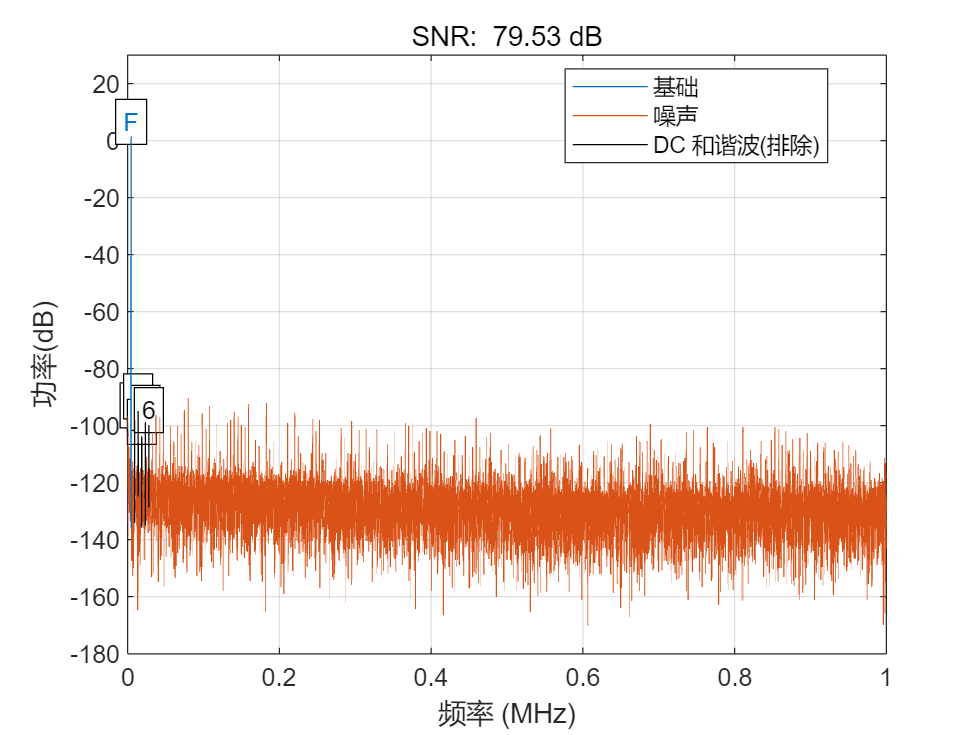

ans = 79.5282

snr(Vout_mean_calib, fs)

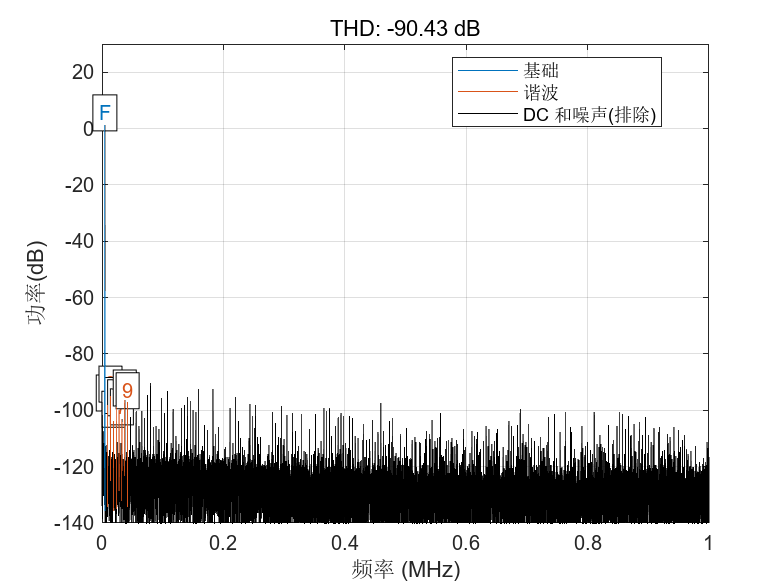

ans = -90.4284

thd(Vout_mean_calib, fs, 9, "aliased")

## Gain Sweep

gain_sweep = 15:0.001:16;
sinad_sweep = zeros(size(gain_sweep));
thd_sweep = zeros(size(gain_sweep));
for i = 1:length(gain_sweep)
    Vout_sweep = Calib_Gain(Vout_N4, gain_sweep(i));
    sinad_sweep(i) = sinad(Vout_sweep, fs);
    thd_sweep(i) = thd(Vout_sweep, fs, 9, 'aliased');
end

max(sinad_sweep)
min(thd_sweep)
sinad_index = find(sinad_sweep == max(sinad_sweep))
thd_index = find(thd_sweep == min(thd_sweep))
gain_sweep(sinad_index)
gain_sweep(thd_index)


figure1 = figure('InvertHardcopy','off','NumberTitle','off','Name','Gain Sweep','Color',[1 1 1]);
    % figure1.width = 600;
    % figure1.height = 400;
    figure1.Position = [100 100 600 450];
    
    % 创建 axes
    axes1 = axes('Parent',figure1);
    hold(axes1,'on');
    
    % 使用 plot 的矩阵输入创建多行
    yyaxis left

    plot1 = plot(gain_sweep, sinad_sweep,'LineWidth',2);
    set(plot1(1),'DisplayName','Power',...
        'Color',[0 0 1]);

    ylabel('SNDR (dB)','FontWeight','bold','FontName','Times New Roman', 'Color',[0 0 1]);

    yyaxis right
    plot2 = plot(gain_sweep ,thd_sweep,'LineWidth',2);
    set(plot2(1),'DisplayName','Fit Curve','Color',[1 0 0]);
    ylabel('THD (dB)','FontWeight','bold','FontName','Times New Roman', 'Color',[1 0 0]);
%     % 创建 ylabel
    
    % 创建 xlabel
    xlabel('Gain','FontWeight','bold',...
        'FontName','Times New Roman');

    % 创建 title
%     title('FFT (102400 Samples)','FontWeight','bold',...
%         'FontName','Times New Roman');
% 
%     % 创建 text annotation
%     text_sndr = join(['SNDR: ', num2str(sinad_tot,'%.2f'), ' dB']);
%     text_snr = join(['SNR: ', num2str(snr_tot,'%.2f'), ' dB']);
%     text_thd = join(['THD: ', num2str(thd_tot,'%.2f'), ' dB']);
%     text_str = {text_sndr, text_snr, text_thd};
% 
%     t1 = text(2E5,-30,text_str, 'HorizontalAlignment','left','FontSize',15, ...
%     'FontWeight','bold','FontName','Times New Roman');
%     t1.BackgroundColor = [1,1,1];

    % 取消以下行的注释以保留坐标区的 X 范围
%     xlim(axes1,[-95 0]);
    % 取消以下行的注释以保留坐标区的 Y 范围
%     ylim(axes1,[-10 95]);
    box(axes1,'on');
    grid(axes1,'on');
    hold(axes1,'off');
    % 设置其余坐标区属性
    set(axes1,'FontName','Times New Roman','FontSize',15,'FontWeight','bold',...
        'LineWidth',2);
createfigure_GainSweep(gain_sweep, sinad_sweep, thd_sweep)

figure
yyaxis left
plot(gain_sweep, sinad_sweep);

ylabel("SNDR [dB]")
yyaxis right
plot(gain_sweep ,thd_sweep)
ylabel("THD [dB]")
xlabel("Gain")
grid on

## Periodgram

Vout_mean_calib_seg = Vout_mean_calib(1:M*20);

figure
sinad(Vout_mean_calib_seg, fs)

Vout_mean_win = kaiser(M*20, 38) .* Vout_mean_calib_seg;
% 
% figure
% periodogram(Vout_mean_win, rectwin(N_Sample/Num_2pi), N_Sample/Num_2pi, 'onesided',fs, 'power');
xdft = fft(Vout_mean_win);
xdft = xdft(1:length(Vout_mean_win)/2+1);
psdx = (1/(fs*length(Vout_mean_win))) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1)*(length(Vout_mean_win))*(sum(kaiser(M,38)/M));
freq = 0:fs/length(Vout_mean_win):fs/2;

figure
plot(freq, pow2db(psdx))
grid on 

[pxx, f] = periodogram(Vout_mean_calib_seg, kaiser(M*20, 38), M*20, 'onesided',fs, 'power');
figure
plot(f, 10*log10(pxx));
grid on
p_fin = pxx(f == fin);
p_tot = sum(pxx) - p_fin;

s = 10*log10(p_fin / p_tot)
figure
periodogram(Vout_mean_calib, hanning(N_Sample), N_Sample, 'onesided',fs, 'power');

## Segment calculation

Seg_num = 5
% Seg_len = M*(Num_2pi / Seg_num);
% Seg_sinad = zeros(Seg_num, 1);
% Seg_thd = zeros(Seg_num, 1);
% Seg_pxx = zeros(Seg_num, Seg_len/2+1);
% 
% for i=1:Seg_num
%     index_head = (i-1)*Seg_len+1;
%     index_tail = i*Seg_len;
%     Vout_mean_calib_seg = Vout_mean_calib(index_head:index_tail);
%     Seg_sinad(i) =  sinad(Vout_mean_calib_seg, fs);
%     Seg_thd(i) = thd(Vout_mean_calib_seg, fs, 9, "aliased");
% 
%     [Seg_pxx(i,:), Seg_f] =  periodogram(Vout_mean_calib_seg, kaiser(Seg_len, 38), Seg_len, 'onesided',fs, 'power');
% 
% end
[Seg_f, Seg_pxx, ~, ~ ] = Seg_Periodgram(Seg_num, M, Num_2pi, [Vout_mean_calib, Vout_without_calib], fs);
% [Seg_f, Seg_pxx, ~, ~ ] = Seg_Periodgram(Seg_num, M, Num_2pi, Vout_without_calib, fs);
% mean(Seg_pxx)
% plot(Seg_f, 10*log10(mean(Seg_pxx)))

figure
semilogx(Seg_f, 10*log10(Seg_pxx))


## 功耗计算

sfdr(Vout_mean_calib, fs);

power = [151E-6, 56.9E-6, 639E-6, 9.11E-3];     % A
totPower = sum(power) * 1.8                     % w
sndr = 82.32;
dr = 90.8;
enob = (sndr-1.78) / 6.02
Foms_sndr = sndr + 10*log10(1E6 / totPower)
Foms_dr = dr + 10*log10(1E6 / totPower)
Fomw = totPower/(2^enob*2E6)

function V_calib = Calib_Gain(V_uncalib, GainA)
    V_calib = zeros(length(V_uncalib),1);
%     V_calib = V_uncalib(:,1) +
    for i = 1:4
        V_calib = V_calib + (V_uncalib(:,i) / GainA^(i-1));
    end    
end

